clear;
load processed_thruster_data.mat;
dataEst = data_square;
dataVal = data_sine;

% delay in sampling times
nk = delayest(dataEst)

nk = 17

% prepare srivcstruc
% parameter numbers numerator
nb_min = 1; nb_max = 4;
% parameter numbers denominator
nf_min = 1; nf_max = 4;
% range of delay in sampling times
nk_min = nk; nk_max = nk + 1;

nn = [nb_min nf_min nk_min;
        nb_max nf_max nk_max];
% we supply dataValid, cross validation is integrated
V = srivcstruc(dataEst, dataVal, nn);


Elapsed time :  0 h  0 min 25 s 




    Note: The value for 'Nmodels' is greater than the number of available models.



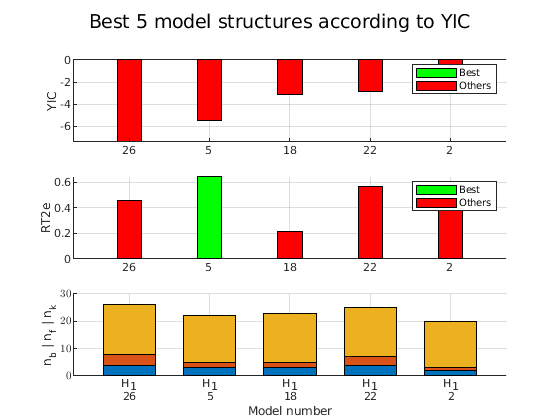

% display ten best model structures
selcstruc(V,'srivc','Nmodels',10);

% since its not easy to tell by visual inspection which is best:
numberModels = size(V, 1);
NN = V(1:end, 1:3);
YIC = V(1:end, 4);
RT2e = V(1:end, 5);
% specify here how YIC and RT2e shall be weighted compared to each other
score = - YIC + RT2e;
[scoreSorted, indices] = sort(score, 'descend');
models = 1:numberModels;
modelsSortedByScore = models(indices);
% interesting: what is the heightest RT2e value we got? Tells us something
% about how noisy data is
max_RT2e = max(RT2e)

max_RT2e = 0.6392

% not very high! data quite noisy

bestModelNumber = 1;
% model four also seems good!
nb_best = V(bestModelNumber, 1)

nb_best = 1

nf_best = V(bestModelNumber, 2)

nf_best = 1

nk_best = V(bestModelNumber, 3)

nk_best = 17

M = srivc(dataEst, [nb_best nf_best nk_best]);
present(M);

                                                                                                                     
M =                                                                                                                  
Continuous-time OE model: y(t) = [B(s)/F(s)]u(t)                                                                     
  B(s) = 1.143 (+/- 0.02749)                                                                                         
                                                                                                                     
  F(s) = s + 35.06 (+/- 0.9301)                                                                                      
                                                                                                                     
Input delays (listed by channel): 0.034                                                                              
Parameterization:                                       

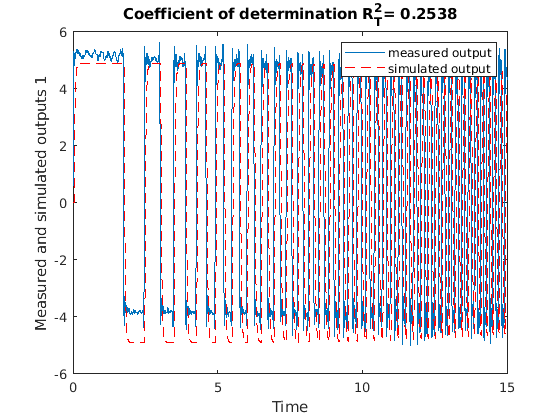

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% second order one zero model (plus small delay)
figure;
comparec(dataEst, M)

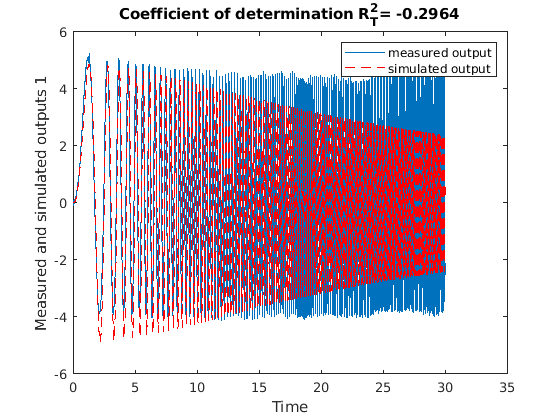

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


comparec(dataVal, M)

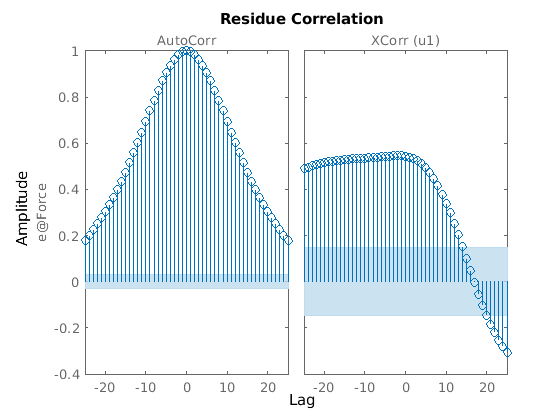

resid(dataEst, M)

% low cross correlation with input, but high auto correlation of residuals!